load('baseballstats.mat', 'Batting', 'Names', 'Salaries');

One of the first things that I want to do is divide the Batting table up by year. I use the findgroups() command. Here, I use [findgroups() and splitapply() ](http://blogs.mathworks.com/loren/2015/11/03/analyzing-baby-names-with-matlab-r2015b/#5c0cf125-9854-47d6-a1d3-e9cb0371cd01)to find the max number of doubles in each season over time

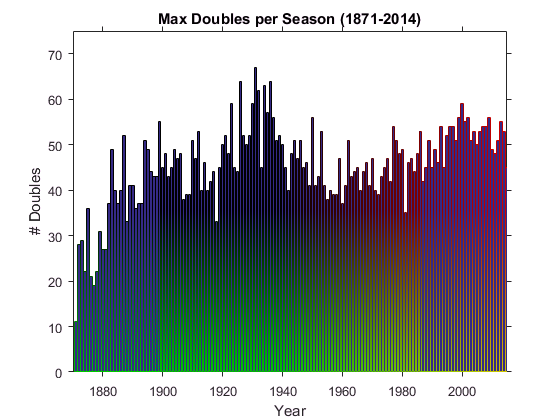

%% start batting analysis
Gyear = findgroups(Batting.yearID);
figure
bar(unique(Batting.yearID), splitapply(@max, Batting.x2B, Gyear));
title('Max Doubles per Season (1871-2015)')
ax = gca;
ax.TickDir = 'out';
ax.YLim = [0 75];
ax.XLim = [1870 2015];
ax.XLabel.String = 'Year';
ax.YLabel.String = '# Doubles';
print('images/doublesovertime.png', '-dpng');

clear ax;

Now I want to see if there is a correlation between the maximum number of doubles and the total number of hits

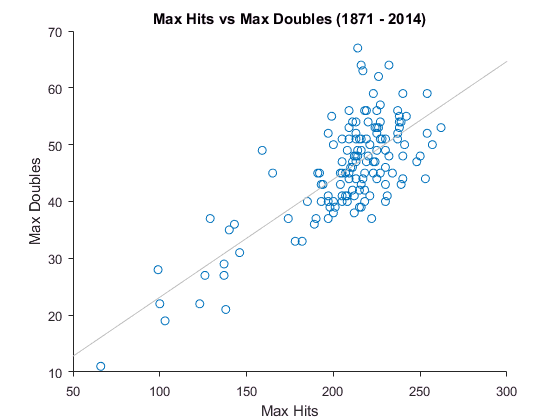

figure
scatter(splitapply(@max, Batting.H, Gyear), splitapply(@max, Batting.x2B, Gyear));
lsline;
title('Max Hits vs Max Doubles (1871 - 2015)');
ax = gca;
ax.XLabel.String = 'Max Hits';
ax.YLabel.String = 'Max Doubles';
ax.TickDir = 'out';
print('images/maxhitsvsmaxdoubles.png', '-dpng');

clear Gyear ax;



Now lets see if we can find Pete Rose

[Gplayer, players] = findgroups(Batting.playerID);
[~, idx] = max(splitapply(@sum, Batting.H, Gplayer));
getPlayerName(players(idx), Names)

ans =     nameFirst    nameLast
    _________    ________

    Pete         Rose    


clear Gplayer players idx ans;

Let's make a boxplot showing offensive stats over the last ten years for the Phillies.

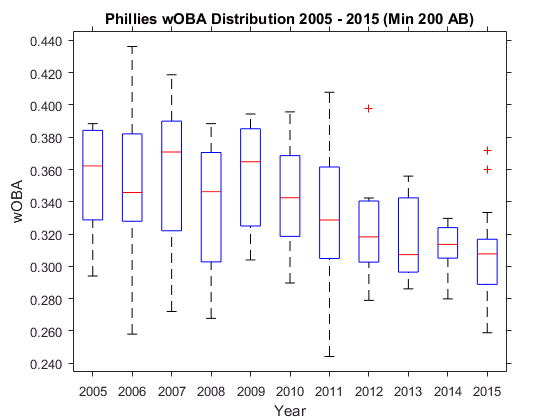

Phillies = Batting(Batting.teamID == 'PHI' & Batting.yearID >= 2005 & Batting.yearID <= 2015 & Batting.AB >= 200, :);
figure
boxplot(Phillies.wOBA, Phillies.yearID);
title('Phillies wOBA Distribution 2005 - 2015 (Min 200 AB)');
ax = gca;
ax.XLabel.String = 'Year';
ax.YLabel.String = 'wOBA';
ax.YAxis.TickLabelFormat = '%.3f';
ax.TickDir = 'out';
print('images/Phillies wOBA.png', '-dpng');

clear ax;

Let's check out offensive statistic performance against salaries.

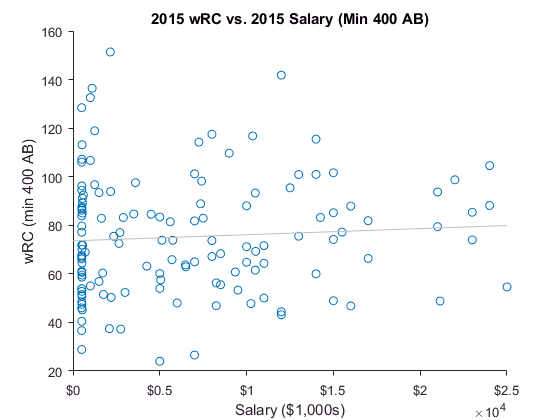

wRC = Batting(Batting.yearID == 2015 & Batting.AB >= 400,{'playerID', 'wRC'});
salary = Salaries(Salaries.yearID == 2014, {'playerID', 'salary'});
S = outerjoin(wRC, salary);
S = S(~isundefined(S.playerID_wRC) & ~isundefined(S.playerID_salary),:);
figure;
scatter(single(S.salary) / 1000 , S.wRC);
title('2015 wRC vs. 2015 Salary (Min 400 AB)');
lsline;
ax = gca;
ax.XLabel.String = 'Salary ($1,000s)';
ax.YLabel.String = 'wRC (min 400 AB)';
ax.XAxis.TickLabelFormat = '$%,g';
ax.TickDir = 'out';

clear clear ax mu S wRC salary2014;